# Poisson Equation with Neumann Boundary Condition

We've seen in `a_poisson.mlx` how to solve Poisson Equation with Dirichlet boundaries. Now let's see how Neumann boundary is solved in MatFem.

The Poisson Equation with Neumann bound:


$$\ -\Delta u = f,\qquad \text{in }\Omega\;,\\
\ \ \ \ \,u = g,\qquad \text{on }\partial\Omega_1\;,\\
\nabla u\cdot \mathbf{n} = h,\qquad \text{on }\partial \Omega_2\;.$$


## Test case

Let our analytical solution be


$$u=e^{x+y} \text{ }\ldotp$$


Then


$$\begin{array}{l}
f=−2e^{x+y} \text{ },\\
g=e^{x+y} \text{ },\\
h=−e^{x+y} \text{ }\ldotp 
\end{array}$$


u = @(x,y) exp(x+y);
f = @(x,y) -2*exp(x+y);
g = @(x,y) exp(x+y)/all(x==1|x==-1|y==1); % Ensure input points are on boundar
h = @(x,y) -exp(x+y);

## Domain and Function Space

Let $\Omega$ be the square $[-1,1]\times[-1,1]$. Let the bottom edge be the Neumann boundary $\partial\Omega_2$ and the rest are the essential boundary $\partial\Omega_1$.

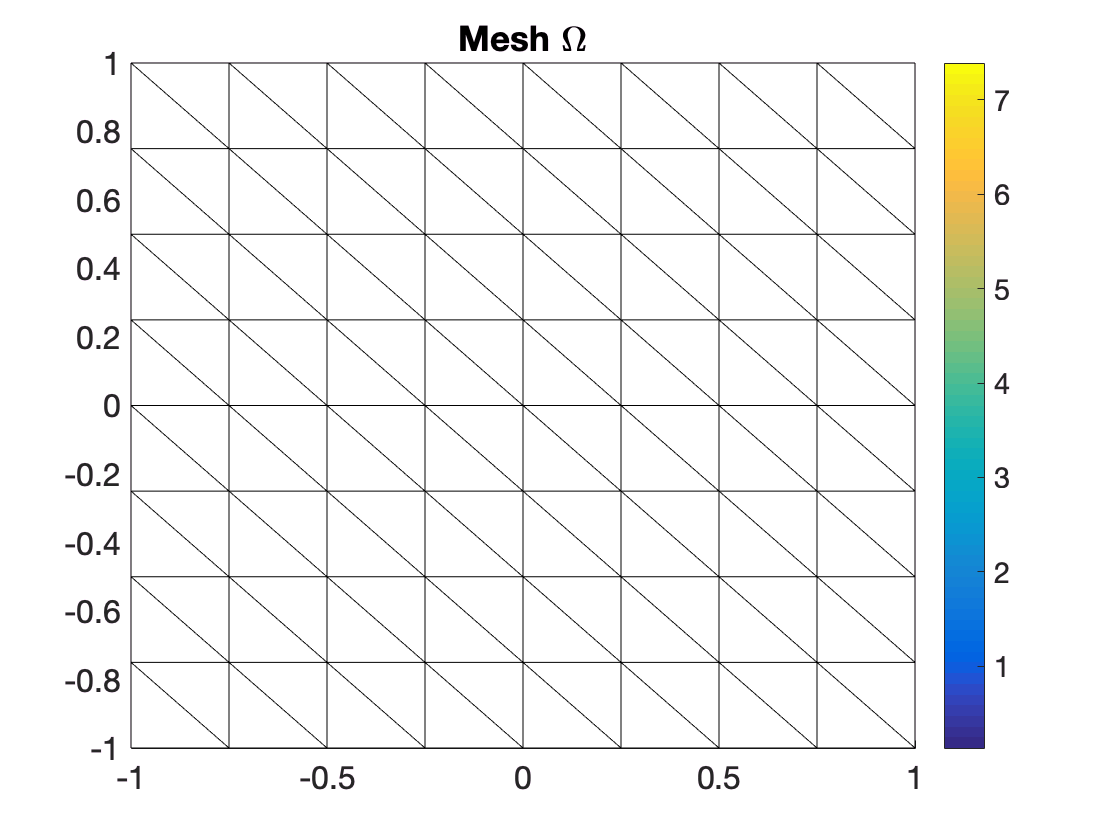

addpath('..')
domain = [-1 1 -1 1];
mesh = MatFem.rectMesh(domain, 8);
mesh.plot();
title('Mesh \Omega')

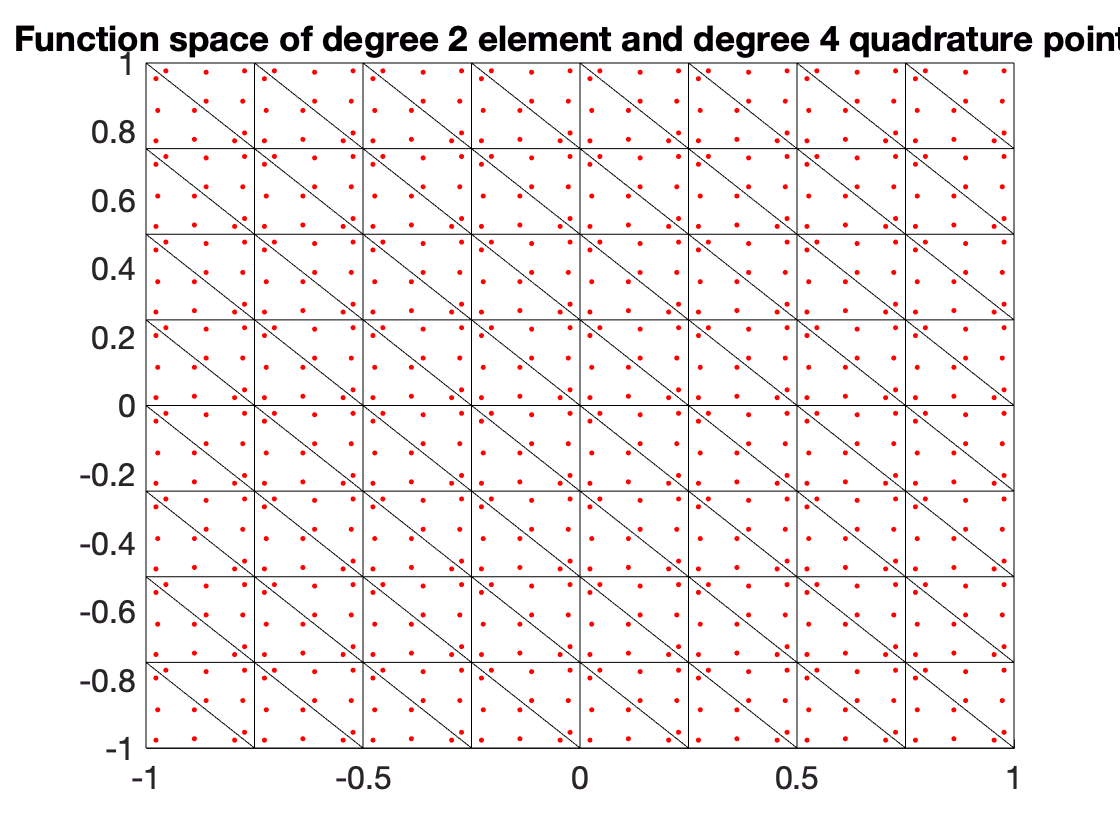

V = MatFem.mesh2spc(mesh, 2, 4);
figure()
V.plot()
title('Function space of degree 2 element and degree 4 quadrature points')

Plot true solution $e^{x+y}$

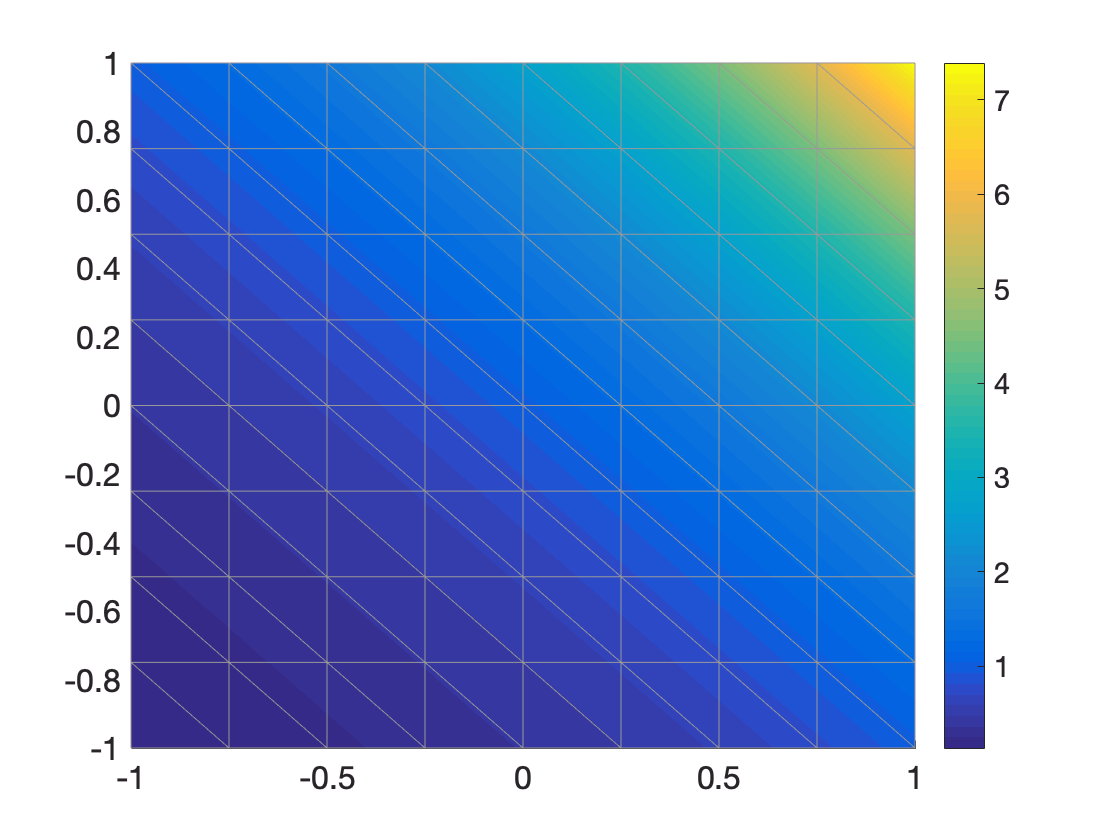

figure()
V.plotu(u)

## Variational form

Since we now have a Neumann boundary condition, our variational form becomes


$$\int_\Omega\nabla v\cdot\nabla u=\int_\Omega fv+\int_{\partial\Omega_2}vh\;.$$


The only difference from the previous example in `a_poisson.mlx` is the second term, which is an integration on part of the boundary. This is also handled by our `bndCond` class.

## Boundary Conditions

We will use the `boundMarker` argument in `rectBndCond` to mark all the boundaries, with a marker `1` for Dirichlet boundary and `2` for Neumann boundary.

boundMarker = [1 2 1
               1 0 1
               1 1 1];
bc = MatFem.rectBndCond(V, boundMarker, domain);

The `boundMarker` argument can be a $3\times3$ matrix, corresponds to the marker for


$$\left\lbrack \begin{array}{c}
left–bottom\text{ }corder & bottom\text{ }edge & right–bottom\text{ }corner\\
left\text{ }edge & \text{ } & right\text{ }edge\\
left–top\text{ }corner & top\text{ }edge & right–top\text{ }corner
\end{array}\right\rbrack$$


Note:

- The center element `boundMarker(2,2)` is of no use

- The first row corresponds to the bottom of the domain, which is somehow anti-intuitive. The reason for this design is: the first row of the `rectMesh` are the bottom. The numbering for nodes start from the bottom.

## Assemble and Solve

Most part here is the same as in `a_poisson.mlx`. The integration on $\partial\Omega_2$ is implemented by `bndCond.applyEdge()`. This works similarly as `assemble`, but integrate only on boundaries with given marker.

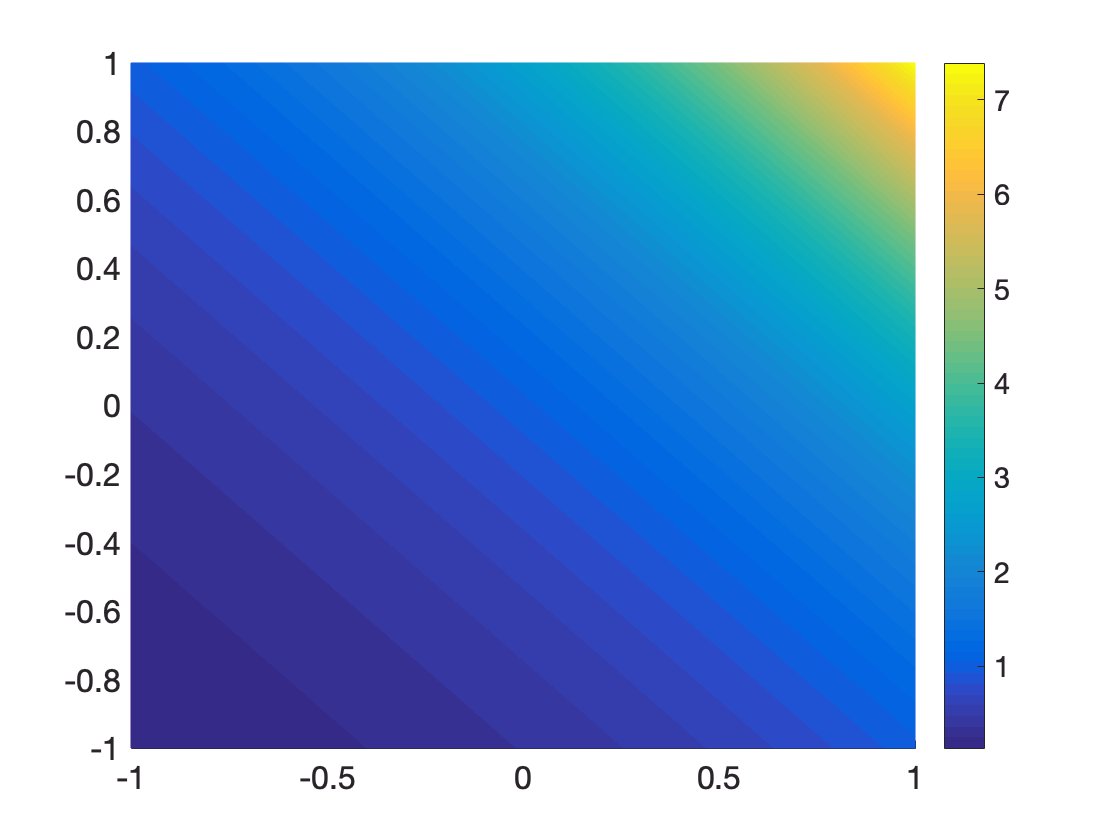

import MatFem.assemble
% Integration on $\Omega$
A = assemble(V, [1 0; 1 0]);        % dudx*dvdx on Ω
A = A + assemble(V, [0 1; 0 1]);    % dudy*dvdy on Ω
b = assemble(V, [0 0], f);          % f*v on Ω

% Integration on boundary (Neumann condition)
b = b + bc.applyEdge(2, [0 0], h);  % h*v on ∂Ω_2

% Apply Dirichlet boundary
[b, A] = bc.applyDir(1, g, b, A);

% Solve
u_n = A \ b;

% Plot
V.plotu(u_n, 'EdgeColor', 'interp')

## Errors

 $\frac{\partial u}{\partial x}=\frac{\partial u}{\partial y}=u$.

dudx = u;
dudy = u;
MatFem.calcErrors(V, u_n, u, {dudx, dudy}, 1/8)

ans =       h      error_inf     error_L2     error_H1
    _____    _________    __________    ________
    '1/8'    0.0021742    0.00086563    1.5105  

Convergence check

run poisson_neumann.m

       h       error_inf      error_L2     error_H1
    _______    __________    __________    ________
    '1/8'        0.012047     0.0045369     0.17431
    '1/16'      0.0032895     0.0012029    0.089753
    '1/32'     0.00086065    0.00030997    0.045561
    '1/64'     0.00022019    7.8693e-05    0.022956
    '1/128'    5.5694e-05    1.9826e-05    0.011523
Elapsed time is 6.668785 seconds.
